# Generating Two Dimensional Log Chroma Histogram from Raw Sensor Data

***Siddhant Sahu, Jean Baptiste Thomas, Jon Yngve Hardeberg***

*Norwegian Colour and Visual Computing Lab, Norwegian University of Science and Technology, Gjovik, Norway*

clear, clc;

## Enter the filename and the Bayer pixel arrangement of camera,

'rggb','bggr','gbrg' or 'grbg' - -

filename = 'right_lamp.dng';
bayer_type = 'rggb';

## Define transformation matrix from sRGB space to XYZ space for later use

srgb2xyz = [0.4124564 0.3575761 0.1804375;
    0.2126729 0.7151522 0.0721750;
    0.0193339 0.1191920 0.9503041];

## Reading DNG file from Adobe RAW to DNG Converter output

warning off MATLAB:tifflib:TIFFReadDirectory:libraryWarning
t = Tiff(filename,'r');

offsets = getTag(t,'SubIFD');
setSubDirectory(t,offsets(1));

raw = read(t);
close(t);
meta_info = imfinfo(filename);
x_origin = meta_info.SubIFDs{1}.ActiveArea(2)+1;
width = meta_info.SubIFDs{1}.DefaultCropSize(1);
y_origin = meta_info.SubIFDs{1}.ActiveArea(1)+1;
height = meta_info.SubIFDs{1}.DefaultCropSize(2);
raw = double(raw(y_origin:y_origin+height-1,x_origin:x_origin+width-1));

## Linearize

if isfield(meta_info.SubIFDs{1},'LinearizationTable')
    ltab=meta_info.SubIFDs{1}.LinearizationTable;
    raw = ltab(raw+1);
end
black = meta_info.SubIFDs{1}.BlackLevel(1);
saturation = meta_info.SubIFDs{1}.WhiteLevel;
lin_bayer = (raw-black)/(saturation-black);
lin_bayer = max(0,min(lin_bayer,1));
clear raw

## Camera's Auto White Balance

wb_multipliers = (meta_info.AsShotNeutral).^-1;
wb_multipliers = wb_multipliers/wb_multipliers(2);
mask = wbmask(height,width,wb_multipliers,bayer_type);
balanced_bayer = lin_bayer .* mask;
%clear lin_bayer mask

## Colour Correction Matrix from DNG Info

temp = meta_info.ColorMatrix2;
xyz2cam = reshape(temp,3,3)';

## Demosaicing

temp = uint16(lin_bayer/max(lin_bayer(:))*2^16);
lin_rgb = single(demosaic(temp,bayer_type))/65535;
clear balanced_bayer temp

## Manual White Balance from Colour Checker

illu_x = 754;
illu_y = 1997;
light_color = [lin_rgb(illu_x,illu_y,1), lin_rgb(illu_x,illu_y,2), lin_rgb(illu_x,illu_y,3)];
wb_mul = (light_color(:)/light_color(2)).^-1;
wb_ccm = [wb_mul(1) 0 0;
    0 wb_mul(2) 0;
    0 0 wb_mul(3)];
balanced_lin_bayer = apply_cmatrix(lin_rgb, wb_ccm);
balanced_lin_bayer = max(0,min(balanced_lin_bayer,1));

## For Viewing Purpose

#### Colour Space Conversion 

rgb2cam = xyz2cam * srgb2xyz;
rgb2cam = rgb2cam ./ repmat(sum(rgb2cam,2),1,3);
cam2rgb = rgb2cam^-1; 

lin_srgb = apply_cmatrix(balanced_lin_bayer,cam2rgb);
lin_srgb = max(0,min(lin_srgb,1));


#### Brightness and Gamma

grayim = rgb2gray(lin_srgb);
grayscale = 0.25/mean(grayim(:));
bright_srgb = min(1,lin_srgb*grayscale);
clear lin_srgb grayim

#### Display and Save

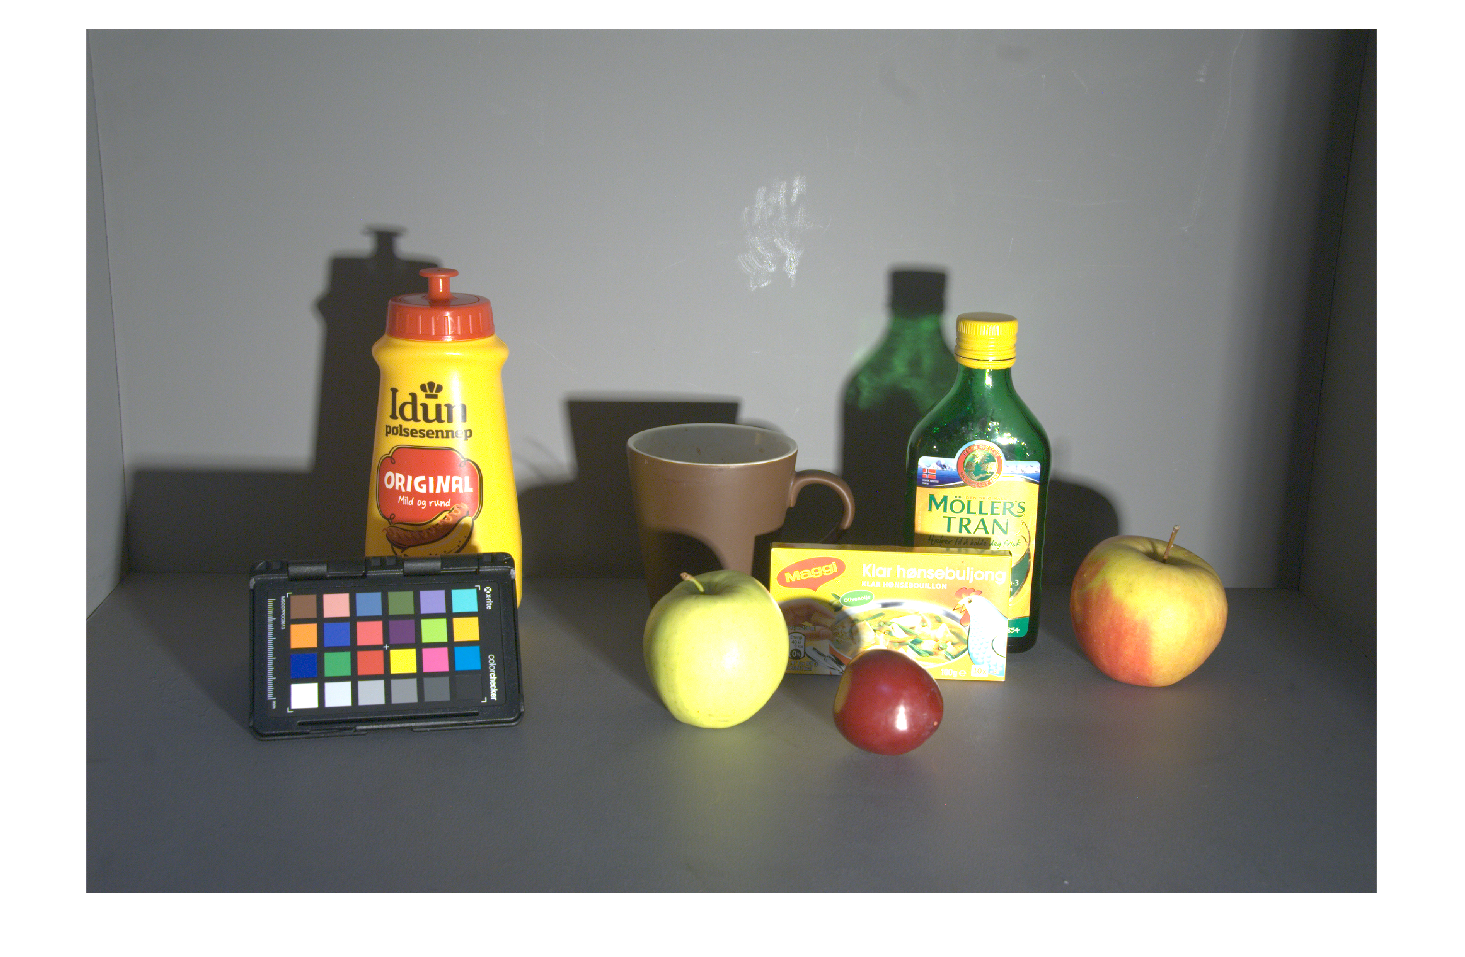

nl_srgb = bright_srgb.^(1/2.2); 

f1 = figure(1);
imshow(nl_srgb);
saveas(f1, 'right_lamp.png');

## Generate Log Chroma Histogram

The log chroma histogram has two dimension $u$ and $v$ which are defined as follows, 

$u^{(k)} = log(I_g^{(k)}/I_r^{(k)})$ and $v{(k)} = log(I_g^{(k)}/I_b^{(k)})$

where $k$ is the particular pixel and $I_r, I_g, I_b$ are its corresponding red, green and blue values.

uv_0 = -1.421875;
bin_size = 1 / 64;
bin_num = 256;

[h, w, ~] = size(balanced_lin_bayer);
I_log = log(single(balanced_lin_bayer)); %all values of I_log = -ve as lin_rgb 0<-1
u = I_log(:, :, 2) - I_log(:, :, 1); %mix of +ve and -ve values mosty between 0 and 1
v = I_log(:, :, 2) - I_log(:, :, 3);

% calculate mask
valid = ~isinf(u) & ~isinf(v) & ~isnan(u) & ~isnan(v);

hist = zeros(256, 256); %initializing the histogram
% iterating over the entire image and plot the log chroma histogram
for i = 1:h 
    for j = 1:w 
        if (valid(i, j)) 
            u_val = round((u(i, j) - uv_0) / bin_size); 
            v_val = round((v(i, j) - uv_0) / bin_size); 
            u_val = max(min(u_val, 256), 1); 
            v_val = max(min(v_val, 256), 1); %after this we know which bin to in
            hist(u_val, v_val) = hist(u_val, v_val) + 1; 
        end 
    end 
end 
hist = hist / max(eps, sum(hist(:))); %normalize of hist

## Visualize the Histogram

`eq 8 in CCC Paper, normalize histogram`

if ~exist('rho', 'var')
  rho = 0.5;
end

if any(hist(:) < 0)
  max_val = max(max(abs(hist), [], 1), [], 2);
  hist = bsxfun(@rdivide, hist, max_val);
  hist = sign(hist) .* (abs(hist).^rho); 
  hist = (hist + 1) / 2;
else
  hist = bsxfun(@rdivide, hist, max(max(hist, [], 1), [], 2));
  hist = hist.^rho;
end

#### Plot and Save Histogram

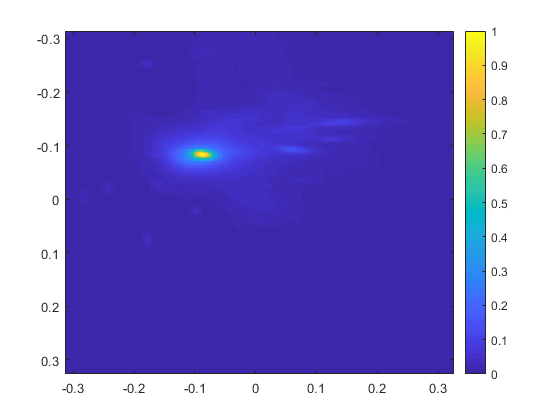

bins_num = 256;
bins = -0.3125 + [0 : 0.0025 ...
  : (0.0025 * (bins_num - 1))];

assert(length(bins) == size(hist,1))
assert(length(bins) == size(hist,2))

[u_hisi, v_hisi] = ndgrid(bins, bins);
log_rgb = cat(3, -u_hisi, zeros(size(u_hisi)), -v_hisi);
rgb = exp(bsxfun(@minus, log_rgb, max(log_rgb, [], 3))); %to create the color square or color wheel
rgb = bsxfun(@rdivide, rgb, max(rgb,[],3));

f2 = figure(2);
imagesc(bins, bins, hist);
colorbar;
saveas(f2, 'rightlamp_imagesc.png');

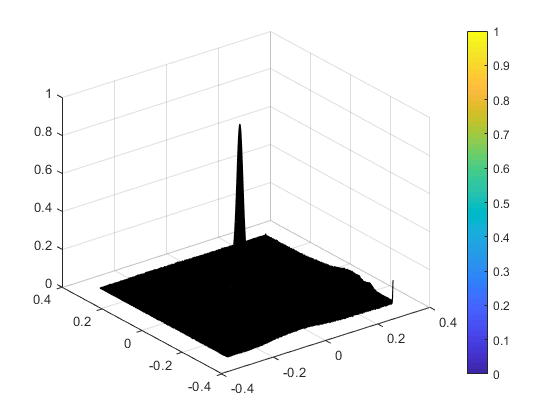


f3 = figure(3);
surf(bins, bins, hist);
colorbar;
saveas(f3, 'rightlamp_surf.png');

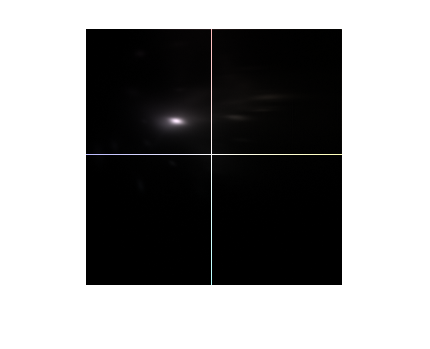



% finding the zero bin index to draw the axis
zero_bin_idx = find(bins == 0);
if (numel(zero_bin_idx) >= 1)
  assert(numel(zero_bin_idx) == 1);
  hist(zero_bin_idx,:,:) = 1;
  hist(:,zero_bin_idx,:) = 1;
end


V = {};
for c = 1:size(hist,3)
  V{c} = bsxfun(@times, hist(:,:,c), rgb);
  if c < size(hist,3)
    V{c} = padarray(V{c}, [2,0], 1, 'post');
  end
end
V = cat(1, V{:});

f4 = figure(4);
imshow(V);
saveas(f4, 'rightlamp_log.png');

## References

- "[Convolutional Color Constancy](https://static.googleusercontent.com/media/research.google.com/en//pubs/archive/44004.pdf)" *Barron* (ICCV 2015) [[Suplementary](https://drive.google.com/file/d/1vO3sVOMihmpNqsuASeR46Y_iME0lOANR/view)] [[Video](https://www.youtube.com/watch?v=saHwKY9rfx0&feature=youtu.be)]

- "[Fast Fourier Color Constancy](http://openaccess.thecvf.com/content_cvpr_2017/papers/Barron_Fast_Fourier_Color_CVPR_2017_paper.pdf)" *Barron et al.* (CVPR 2017) [[Code](https://github.com/google/ffcc)] [[Suplementary](https://drive.google.com/file/d/1b5zdR5UYPTkXa2UgiLhi-PP89bzINJSR/view)] [[Video](https://www.youtube.com/watch?v=rZCXSfl13rY&feature=youtu.be)]

- "[FC4: Fully Convolutional Color Constancy with Confidence-weighted Pooling](http://openaccess.thecvf.com/content_cvpr_2017/papers/Hu_FC4_Fully_Convolutional_CVPR_2017_paper.pdf)" *Hu et al.* (CVPR 2017) [[Code](https://github.com/yuanming-hu/fc4)]

- "[Single and Multiple Illuminant Estimation Using Convolutional Neural Networks](https://ieeexplore.ieee.org/document/7942101)" *Bianco et al.* (TIP 2017)

- "[Recurrent Color Constancy](http://vision.cs.tut.fi/data/publications/iccv2017_recurrent_color_constancy.pdf)" *Qian et al.* (ICCV 2017) [[Code](https://github.com/yanlinqian/RCC-Net)]

- "[Two Illuminant Estimation and User Correction Prefernece](http://openaccess.thecvf.com/content_cvpr_2016/papers/Cheng_Two_Illuminant_Estimation_CVPR_2016_paper.pdf)" *Cheng et al.* (CVPR 2016) [[Webpage](http://cvil.eecs.yorku.ca/projects/public_html/two_illuminant/)]

- "[Deep Specialized Network for Illuminant Estimation](http://personal.ie.cuhk.edu.hk/~ccloy/files/eccv_2016_illuminant.pdf)" *Shi et al.* (ECCV 2016) [[Code](https://github.com/swift-n-brutal/illuminant_estimation)] [[Suplementary](http://mmlab.ie.cuhk.edu.hk/projects/illuminant_estimation/supplemental_v1.pdf)] [[Webpage](http://mmlab.ie.cuhk.edu.hk/projects/illuminant_estimation.html)]

- "[Color Constancy by Deep Learning](https://ivi.fnwi.uva.nl/isis/publications/2015/LouBMVC2015/LouBMVC2015.pdf)" *Lou et al.* (BMVC 2015)

- "[Color Constancy using CNNs](http://openaccess.thecvf.com/content_cvpr_workshops_2015/W03/papers/Bianco_Color_Constancy_Using_2015_CVPR_paper.pdf)" *Bianco et al.* (CVPR 2015)

- "[Effective Learning-Based Illuminant Estimation Using Simple Features](http://cvil.eecs.yorku.ca/projects/public_html/effective/cvpr15.pdf)" *Cheng at al.* (CVPR 2015) [[Code](https://ln.sync.com/dl/67550aaa0/susypm59-v9uzhtda-dczrffgt-84akemde/view/default/7684235510008)] [[Suplementary](http://cvil.eecs.yorku.ca/projects/public_html/effective/cvpr15_suppl.pdf)] [[Webpage](http://cvil.eecs.yorku.ca/projects/public_html/effective/effective.html)]

- "[Computational Color Constancy: Survey and Experiments](https://ieeexplore.ieee.org/document/5719167)" (TIP 2011)

- Color Constancy Marc Ebner

- [https://ipg.fer.hr/ipg/resources/color_constancy](https://ipg.fer.hr/ipg/resources/color_constancy) 